# Microring Resonator

Microring resonators are fundamental building blocks in integrated photonics and are widely used in wavelength filters, modulators, sensors, and nonlinear photonic devices. Their frequency selectivity originates from constructive interference of circulating waves: when the optical phase accumulated over one round trip in the ring matches an integer multiple of $2\pi$, the intracavity field builds up coherently and a resonance is established.

For a single-mode ring waveguide, the **resonance condition** can be written as


$$n_{\textrm{eff}} L=m\lambda_m$$


where $n_{\textrm{eff}}$ is the effective index of waveguide; $L$ is the round-trip optical path length of resonator (for simple circular ring, $L=2\pi R$); $m$ ($m\in {\mathbb{Z}}^+$) is the resonance mode number of the resonator; $\lambda_m$ is the resonant wavelength corresponding to mode number $m$. 

Adjacent resonances are approximately separated by the **free spectral range (FSR)**. Expressed in wavelength, the FSR satisfies


$${\textrm{FSR}}_{\lambda \;} \approx \frac{\lambda^2 }{n_{\textrm{eff}} L}$$


In this example, we demonstrate the capability of the **varFDFD** solver to efficiently handle **photonic simulations at scale** by modeling a microring resonator with a relatively large radius and sweeping the operating wavelength across a narrow spectral window. The workflow highlights both the numerical efficiency of the solver and the characteristic resonance response of an integrated ring resonator.

### Step 0: Global settings

We begin by creating and initializing a `Modelvar3D` object, which serves as the main container for all subsequent configurations, including geometry definition, meshing, solver setup, and result extraction.

modelRR = Modelvar3D.initialize();

Modelvar3D: Object Initialized


In this example, we simulate a **large-radius silicon ring resonator fully buried in silicon dioxide (oxide-clad)**. The structure is fabricated in silicon (Si) and surrounded by silicon dioxide (SiO₂), which acts as both the substrate and the upper cladding. Around the operating wavelength of interest (approximately $1\ldotp 55\;\mu \mathrm{m}$), the refractive indices of these materials are approximately$n_{\rm Si} \approx 3.45$ and $n_{\rm SiO_2} \approx 1.44$.

% material information
n_Si = 3.45; % Si, for device
n_SiO2 = 1.44; % SiO2, for substrate
modelRR.setBackground('eps_r', n_SiO2^2);

### Step 1: Construct device

We use the built-in geometry primitives to construct a large-radius oxide-clad silicon ring resonator. 

#### 1.1 Geometric parameters

The waveguide width is $0\ldotp 48\;\mu \mathrm{m}$, and the silicon device layer thickness is $250\;\textrm{nm}$, both of which are standard values in SOI platforms. The ring center radius is set as $8\;\mu \mathrm{m}$ to demonstrate the capacity of simulating large-scale devices with varFDFD solver.

To enhance coupling efficiency between the straight bus waveguides and the resonator, the ring is split into two half-ring sections connected by straight coupling segements. Each coupling segment has a length of $12\;\mu \mathrm{m}$, and the gap between the ring and the bus waveguide is $100\;\textrm{nm}$.

% ring resonator parameters
R     = 8e-6;      % ring radius (center line)
W_wg  = 0.48e-6;   % waveguide width
W_gap = 0.1e-6;   % coupling gap
L_cp  = 12e-6;      % coupling length
t_Si  = 250e-9;    % Si device layer thickness

#### 1.2 Define device

For a Modelvar3D simulation, the structure is defined as a `LayerDevice`. The ring is constructed using two half-ring geometries with complementary angular spans, and the planar geometry is extruded along the $z$-direction to represent the silicon device layer.

% half ring 1
modelRR.addDevice(1);
modelRR.setDevice(1).setGeometry("Ring", [R-W_wg/2, R+W_wg/2], [-L_cp/2,0], [pi/2, 3*pi/2], 500);
modelRR.setDevice(1).setMaterial(n_Si^2); % Si
modelRR.setDevice(1).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

% half ring 2
modelRR.addDevice(2);
modelRR.setDevice(2).setGeometry("Ring", [R-W_wg/2, R+W_wg/2], [L_cp/2,0], [-pi/2, pi/2], 500);
modelRR.setDevice(2).setMaterial(n_Si^2); % Si
modelRR.setDevice(2).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

% coupling waveguide 1
modelRR.addDevice(3);
modelRR.setDevice(3).setGeometry("Rectangle", L_cp, W_wg, 'c', [0 -R]);
modelRR.setDevice(3).setMaterial(n_Si^2); % Si
modelRR.setDevice(3).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

% coupling waveguide 2
modelRR.addDevice(4);
modelRR.setDevice(4).setGeometry("Rectangle", L_cp, W_wg, 'c', [0 R]);
modelRR.setDevice(4).setMaterial(n_Si^2); % Si
modelRR.setDevice(4).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

% bus waveguide 1 (input-through)
modelRR.addDevice(5);
modelRR.setDevice(5).setGeometry("Rectangle", 40e-6, W_wg, 'c', [0 -(R+W_wg+W_gap)]);
modelRR.setDevice(5).setMaterial(n_Si^2); % Si
modelRR.setDevice(5).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

% bus waveguide 2 (drop-add)
modelRR.addDevice(6);
modelRR.setDevice(6).setGeometry("Rectangle", 40e-6, W_wg, 'c', [0 (R+W_wg+W_gap)]);
modelRR.setDevice(6).setMaterial(n_Si^2); % Si
modelRR.setDevice(6).setEndPoint('zmin', 250e-9, 'zmax', 250e-9+t_Si);

#### 1.4 Complete device defination

modelRR.assembleDevice;

LayerDevice z-overlap detected between device seq: [1 & 2] [2 & 3] [3 & 4] [4 & 5] [5 & 6]


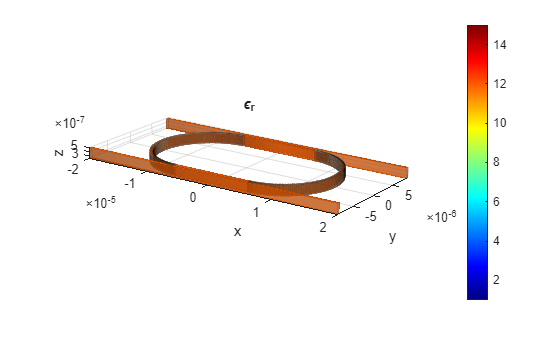

modelRR.device.dispImg;

### Step 2: Set mesh grid

All FDFD solvers use a uniform Cartesian mesh. The mesh is defined by the simulation window size and the grid step along each coordinate direction. The simulation window should fully cover the ring resonator and surrounding cladding while providing sufficient resolution for the waveguide and coupling region.

% grid size (total simulation region)
L = 35e-6; % x-dimension
W = 20e-6; % y-dimension
T = 750e-9; % z-dimension

% pixel step
dx = 25e-9;
dy = 20e-9;
dz = 25e-9;

Nx = round(L/dx);
Ny = round(W/dy);
Nz = round(T/dz);

modelRR.setMesh([Nx Ny Nz], [dx dy dz]);
modelRR.shiftMesh("z", "min", 0);
[x, y, z] = modelRR.getCoordinate;

% mesh device
t_mesh_start = tic;
modelRR.meshDevice;
t_mesh_end = toc(t_mesh_start);
disp(['Device has been meshed, taking time ', num2str(t_mesh_end), ' s.'])

Device has been meshed, taking time 69.5492 s.


### Step 3: Sweep wavelength

To characterize the resonance response of the ring, we sweep the operating wavelength over a narrow band around $1\ldotp 55\;\mu \mathrm{m}$. Since ring resonances are quasi periodic in frequency (${\mathrm{FSR}}_f \approx \frac{c}{n_{\mathrm{eff}} L}$), we create a linear frequency sweep plot of the field.

% wavelength sweep
num_sweep = 9;
c0 = Constant("c0").v; % light speed in vacuum
freq_list = linspace(c0/(1.56e-6), c0/(1.54e-6), num_sweep);  % linear-space frequency points
lam_list = c0./freq_list;

% collect sweeping results
Hz_sweep = zeros(Nx, Ny, Nz, num_sweep);
Ex_sweep = zeros(Nx, Ny, Nz, num_sweep);
Ey_sweep = zeros(Nx, Ny, Nz, num_sweep);

for ii = 1:numel(lam_list)
    t_solve_start = tic;

### Step 4: Configure varFDFD solver

We choose **TM polarization**, which corresponds to a TE-like guided mode in the silicon waveguide cross-section and yields the field components $H_z$, $E_x$, and $E_y$ in the effective 2D problem. The reference probe is placed at `[0,R]`, a location that intersects the oxide–silicon–oxide stack and lies within the ring waveguide, ensuring that the extracted vertical mode profile accurately represents the local guiding environment.

    % varFDFD solver configuration
    modelRR.setWavelength(lam_list(ii));
    modelRR.setSolver("Pol", 'TM', "RefPoint", [0,R]); % choose reference probe across all layers (SiO2-Si-SiO2)

**Perfectly matched layers (PML)** are applied on boundaries of $x-y$ plane to absorb outgoing radiation and suppress boundary reflections. For the varFDFD solver, the boundary condition along the $z$-direction is fixed as a Dirichlet condition, since the $z$-dimension will be collapsed in the variational formulation.

    % PML boundary condition
    modelRR.setBoundary("x", "PML", 15);
    modelRR.setBoundary("y", "PML", 15);

### Step 5: Port and source

A single input port is placed on the straight bus waveguide, and the **fundamental guided eigenmode** is used as the excitation. The port location and span are chosen to fully cover the waveguide cross-section while avoiding interaction with the ring, ensuring a clean modal launch into the bus waveguide. The source automatically inherits the polarization specified in the varFDFD solver configuration.

    % port & source
    modelRR.addPort("+x", -15e-6, [-15e-6 -5e-6]);
    modelRR.addSource(1);

### Step 6: Solve model

    % solve
    modelRR.dispInfo;
    modelRR.solveModel;
    results = modelRR.exportResults;
    
    % collect fields
    Hz_sweep(:,:,:,ii) = results.Hz;
    Ex_sweep(:,:,:,ii) = results.Ex;
    Ey_sweep(:,:,:,ii) = results.Ey;

    t_solve_end = toc(t_solve_start);
    disp(['Sweeping iteration No.', num2str(ii), ' has completed, taking time ', num2str(t_solve_end), ' s.']);
end

=== Modelvar3D Information ===
Wavelength   : 1.560e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.47083
Solved       : No


Sweeping iteration No.1 has completed, taking time 32.0426 s.


=== Modelvar3D Information ===
Wavelength   : 1.557e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.47348
Solved       : No


Sweeping iteration No.2 has completed, taking time 24.6365 s.


=== Modelvar3D Information ===
Wavelength   : 1.555e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.47612
Solved       : No


Sweeping iteration No.3 has completed, taking time 24.1619 s.


=== Modelvar3D Information ===
Wavelength   : 1.552e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.47874
Solved       : No


Sweeping iteration No.4 has completed, taking time 24.2028 s.


=== Modelvar3D Information ===
Wavelength   : 1.550e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.48136
Solved       : No


Sweeping iteration No.5 has completed, taking time 24.6459 s.


=== Modelvar3D Information ===
Wavelength   : 1.547e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.48396
Solved       : No


Sweeping iteration No.6 has completed, taking time 24.2266 s.


=== Modelvar3D Information ===
Wavelength   : 1.545e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.48655
Solved       : No


Sweeping iteration No.7 has completed, taking time 24.11 s.


=== Modelvar3D Information ===
Wavelength   : 1.542e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.48913
Solved       : No


Sweeping iteration No.8 has completed, taking time 24.2014 s.


=== Modelvar3D Information ===
Wavelength   : 1.540e-06 m
Background   : eps_r=2.074, mu_r=1.000
Solver       : var
Mesh (x)     : N=1400, d=2.500e-08 m
Mesh (y)     : N=1000, d=2.000e-08 m
Mesh (z)     : N=30, d=2.500e-08 m
BC (x)       : PML, thickness=15
BC (y)       : PML, thickness=15
Ref point    : [0.000e+00, 8.000e-06] m
Polarization : TM
Source Port  : dir=+x
              x = -1.500e-05 m, y-span = [-1.500e-05, -5.000e-06] m
Source       : Set (type: Source1D, pol: TM)
              src neff = 2.4917
Solved       : No


Sweeping iteration No.9 has completed, taking time 23.731 s.


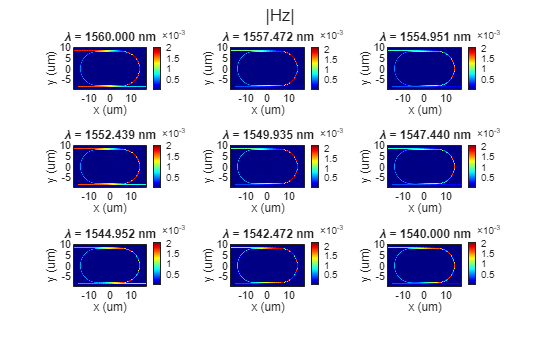

% visulize fields
[~, z_slice_ind] = min(abs(z-0.325e-6));
figure(30); sgtitle('|Hz|')
for ii = 1:num_sweep
    subplot(3,3,ii);
    imagesc(x*1e6, y*1e6, abs(squeeze(Hz_sweep(:,:,z_slice_ind,ii))).');
    xlabel('x (um)'); ylabel('y (um)'); set(gca,'YDir','normal'); axis image;
    colormap jet; colorbar; %clim([0 2.5e-3]);
    title(['\lambda = ', num2str(lam_list(ii)*1e9, '%.3f'), ' nm']);
end